# Analyzing Your Labeled Data

This live script includes the code shown in the prior video and more. Work through the sections below to gain a better understanding of the fastener dataset. 

## Load the Ground Truth

We've labeled the images in the fastener dataset and provided the ground truth for you in the course files. The images were labeled using the Image Labeler App that you saw previously. The mat-file `fastenerTrainGT `contains a variable with the same name that is the ground truth object. 

Run this section to load the ground truth and create the image and box label datastores.

load ("Data\MathWorks Created\Parking Spaces\parkingTrainGTfinished.mat")
load ('parkingTrainGTfinished.mat', 'gTruth')

The function below creates an image and box label datastore for object detection.

[imds, blds] = objectDetectorTrainingData(gTruth);

### View summary of object labels and the LabelData

It is good practice to look at the number of objects and the number of images containing those objects. If you notice that some classes have few objects and/or images, you may need to collect more images or use techniques like data augmentation. Data augmentation is covered in course 3 of this specialization. 

countEachLabel(blds)

ans = 3×3 table
      Label       Count    ImageCount
    __________    _____    __________

    Accessible     167        144    
    Charger        106        106    
    EV             223        201    


## **Create a Table for Analyzing Bounding Boxes**

The data in the box label datastore is structured for the model training functions you'll learn later. The `createBoundingBoxTable` is a helper function located at the bottom of the script that reorganizes the data into a table for analysis and visualization.

bboxes = createBoundingBoxTable(blds)

bboxes = 496×3 table
    ImgIdx               BBox                  Label   
    ______    ___________________________    __________

       1      181      89     114     138    EV        
       2      202     107      76     142    Accessible
       3      189      92     106     187    Accessible
       4      209     116      58     127    Accessible
       5      173      89     135     150    EV        
       6        4      67     181     194    EV        
       7       82      55     216     204    EV        
       8      115    36.5     276     284    EV        
       9      135    65.5     221     255    EV        
      10      201     107      76     141    Accessible
      11      123    54.5     243     266    EV        
      12      156    50.5     172     270    EV        
      13        6     134      58      95    EV        
      13      199     100      82   

### Add area and aspect ratio

The bounding box coordinates for each object is a 1x4 vector. The first two elements are the x and y locations of the upper left corner of the box. The third and fourth elements are the width and height of the bounding box. The code below uses the width and height to calculate the area and aspect ratio of the boxes and adds these quantities to the table.

bboxes.Area = bboxes.BBox(:,3) .* bboxes.BBox(:,4);
bboxes.AspectRatio = bboxes.BBox(:,3) ./ bboxes.BBox(:,4);
bboxes

bboxes = 496×5 table
    ImgIdx               BBox                  Label       Area     AspectRatio
    ______    ___________________________    __________    _____    ___________

       1      181      89     114     138    EV            15732      0.82609  
       2      202     107      76     142    Accessible    10792      0.53521  
       3      189      92     106     187    Accessible    19822      0.56684  
       4      209     116      58     127    Accessible     7366      0.45669  
       5      173      89     135     150    EV            20250          0.9  
       6        4      67     181     194    EV            35114      0.93299  
       7       82      55     216     204    EV            44064       1.0588  
       8      115    36.5     276     284    EV            78384      0.97183  
       9

## Create Visualizations and Analyze Bounding Boxes

### Create a scatter plot

A scatter plot is a good way to determine if there is a relationship between area and aspect ratio. Here, we use a group scatter plot since there are only four categories. Notice that washers and nuts have distinct clusters. However, the area and aspect ratios of bounding boxes for nails and screws vary significantly. This is because orientation impacts the bounding size for these two classes.

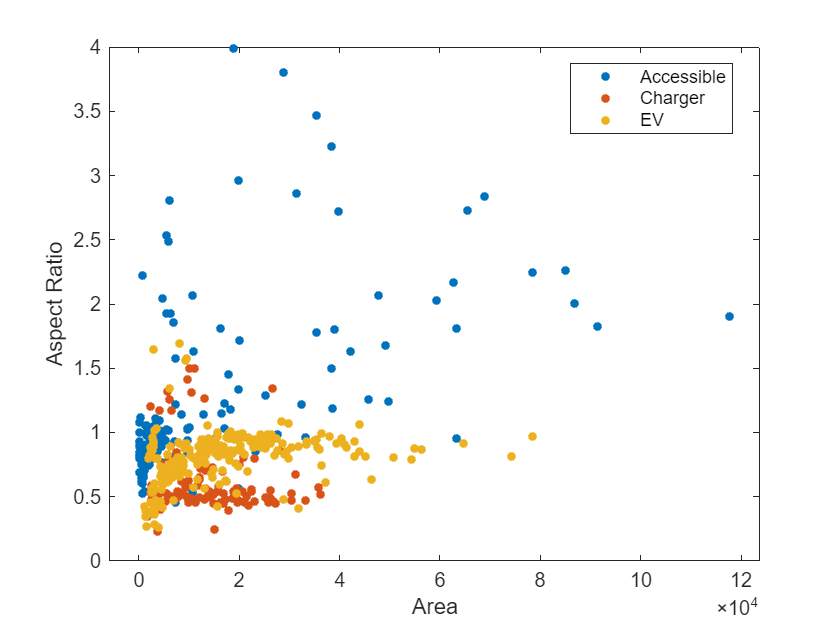

gscatter(bboxes.Area, bboxes.AspectRatio, bboxes.Label)
xlabel("Area")
ylabel("Aspect Ratio")

### Create box plots of aspect ratios for each class

A box plot is a compact way to visualize the distribution of a variable. Here, the distribution of the aspect ratios for each class is shown. 

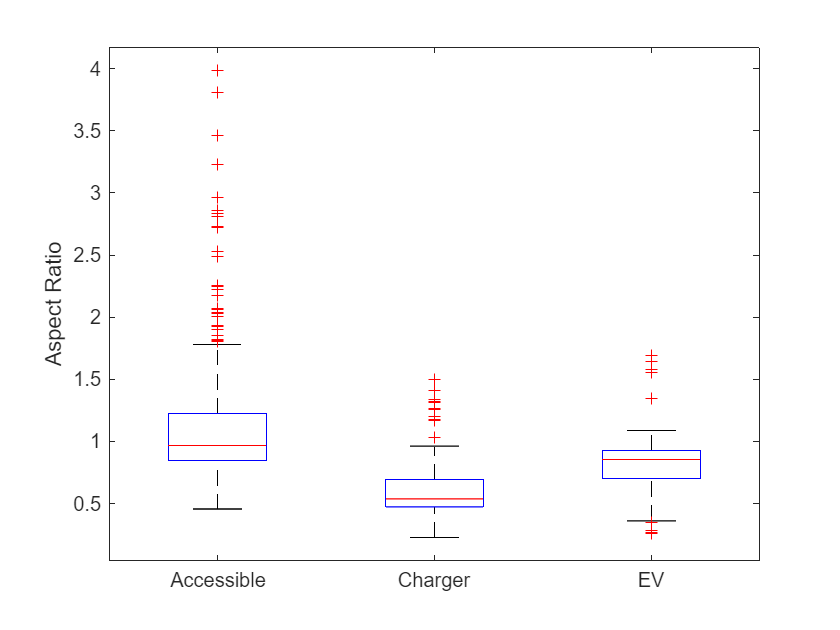

boxplot(bboxes.AspectRatio, bboxes.Label)
ylabel("Aspect Ratio")

### You try: Create a box plot of area for each class

It makes sense that nuts and washers will have aspect ratios near 1. Visualizing the distribution of areas will tell you if there are different sizes of these objects in the images.

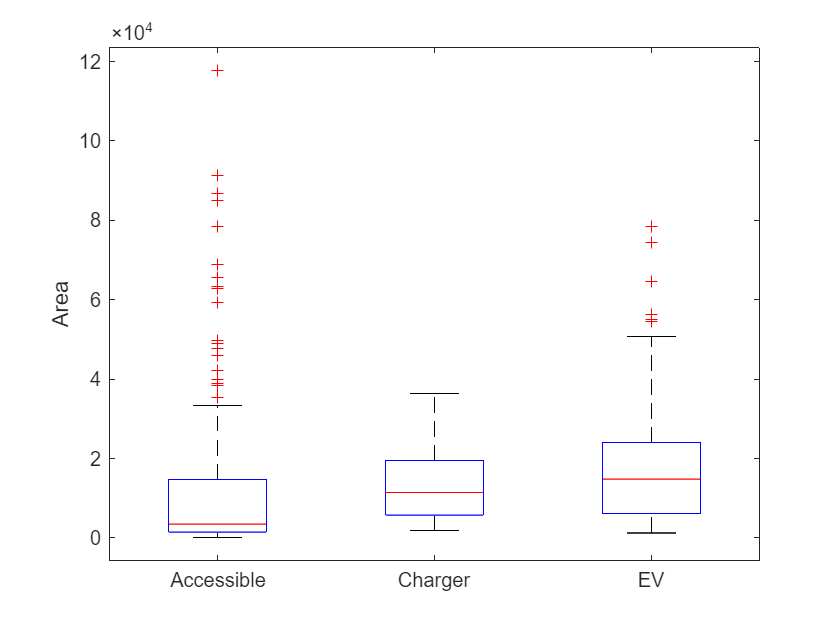

% Create a box plot like that above, but for area
boxplot(bboxes.Area, bboxes.Label)
ylabel("Area")

## Investigate Selected Outliers

Outliers can indicate many different things and are not necessarily bad. In the video, you saw outliers that were normal nails, but at orientations that rarely occurred in the dataset. You also saw an outlier that was a mislabeled image. 

Use the drop-down menus below to find the outliers for a specific class and variable. `displayOutlierImage `is a helper function at the bottom of the script that uses your selections to display the outlier object or message to help you set the controls. 

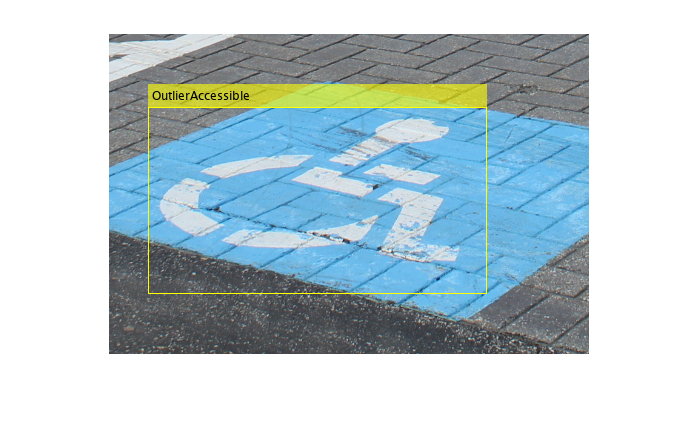

class = "Accessible";
variable = "Area";
outlier2view = 12;
displayOutlierImage(bboxes, class, variable, outlier2view, imds);

nFiles = length(imds.Files)

nFiles = 400

classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


Combine the `imageDatastore` and `boxLabelDatastore` datastores

data = combine(imds,blds);

targetDataSize = [320 480 3]; 
data = transform(data, @(dataIn) resizeDetectionData(dataIn,targetDataSize)); 

## Split the data into training and validation sets

Shuffle the datastore to randomize the files before making the training validation split.

data = shuffle(data);

Next, select a fraction of files to use for training and calculate the number of training files. Here, we keep 80% of the training data as training and use 20% for validation. 

trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);

Finally, use the `subset` function to split the data into training and validation sets.

trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

nTrainData = numTraining

nTrainData = 320

detector = yoloxObjectDetector("tiny-coco",classes,"InputSize", targetDataSize);

## Setup training options and train the detector

Now, set the [training options](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html#namevaluepairarguments) for the optimization algorithm to use. Below, we provide a set of options which work decently well for this application. You'll need to use your insights into the application, data, and almost certainly some trial and error to find the best set of training options for your own work. See the video [Common Training Options](https://www.coursera.org/learn/introduction-deep-learning-computer-vision/lecture/fJQ00/common-training-options) from course one of this specialization for more information.

options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=16,...
    L2Regularization=0.001,... 
    MaxEpochs=10,... 
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=10,...
    Plots = "training-progress",...
    ValidationData=validationData,...
    ValidationFrequency=20,...
    OutputNetwork="best-validation-loss");

The line below is commented since the training can take quite a while depending on the computational resources available to you. (It took us a couple hours using a machine with a GPU.) If you want to give it a try, uncomment below and run the script. 

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingYoloXLoss    ValidationYoloXLoss
    _____    _________    ___________    _________    _________________    ___________________
      1          1         00:00:17        0.001           15.649                11.628       
      1         10         00:02:04        0.001           6.1888                             
      1         20         00:03:12        0.001           5.2847                5.7617       
      2         30         00:04:48        0.001           6.1614                             
      2         40         00:06:07        0.001           4.5408                4.7869       
      3         50 

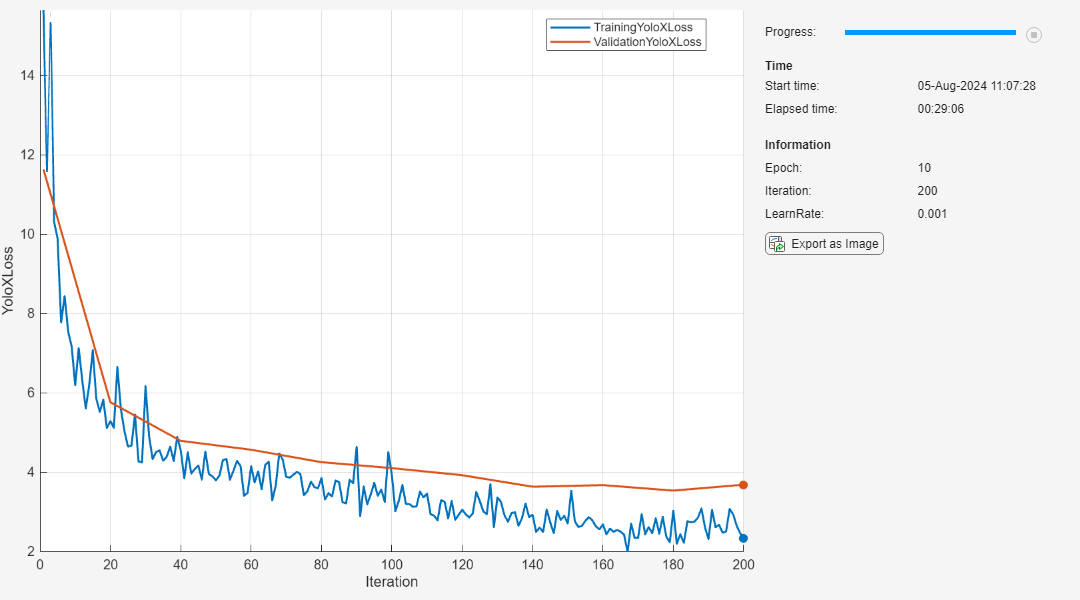

     10         200        00:28:44        0.001           2.3325                 3.682       


[detector,info] = trainYOLOXObjectDetector(trainingData,detector,options);

## Save results

Remember, the model that gets trained as we set this script up is already provided with the course files. If you make changes and want to save your results, make sure to save your model using a different filename.

save('parkingYOLOXObjectDetection.mat', 'detector', 'info');

# Week 3 Quiz

Use this file as a starting point for the week 3 quiz. The code to load the trained model and ground truth for the fasteners dataset is provided. You need to write code to evaluate the model and answer the questions in the Coursera quiz. Refer to the EvaluatingObjectDetectionModels.mlx file for assistance.

load ('C2-ObjectDetection\module 4\ParkingYoloXDetectorSolution.mat', 'detector')
load ('parkingTestGT.mat', 'parkingTestGT')

## Write code to evaluate the model

To complete this week's quiz you need to do the following steps:

- Run the detector on the test images with a confidence threshold of 0.05

- Evaluate the detection results using an IoU threshold of 0.5 and 0.25

- Compare the AP of all classes at both IoU thresholds

- Compare the mAP at both IoU thresholds

[imds, blds] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imds, blds);

## **Run the detector on the test images**

The first step to evaluate your detector is to run the detector on your test images with a small confidence threshold. In the code below, we use 0.05. This means the detector is not picky and will return many detections, even if they have low confidence. 

It took us about 10 seconds to run this on the 240 test images using a decently powered CPU. If you have a supported GPU, MATLAB will automatically use the GPU. 

Examine the output table. Notice that the detector didn't detect any objects in some images and detected multiple objects in others.

testResults = detect(detector, testData, "Threshold", 0.05)

testResults = 100×3 table
                     Boxes                        Scores            Labels      
    _______________________________________    ____________    _________________

    {[ 196.4973 109.6683 88.1484 103.7858]}    {[  0.8485]}    {[EV           ]}
    {[ 136.3007 32.5921 195.3971 231.0662]}    {[  0.8396]}    {[EV           ]}
    {2×4 single                           }    {2×1 single}    {2×1 categorical}
    {[186.3404 101.3398 110.4771 124.9689]}    {[  0.8615]}    {[EV           ]}
    {[ 128.1510 45.2833 203.2499 239.0473]}    {[  0.7650]}    {[EV           ]}
    {4×4 single                           }    {4×1 single}    {4×1 categorical}
    {2×4 single                           }    {2×1 single}    {2×1 categorical}
    {2×4 single                           }    {2×1 single}    {2×1 categorical}
    {2×4 single                           }    {2×1 single}  

### Out of memory errors

When passing a `datastore` to the detect function a batch of images is pulled into memory for detection. Depending on the type of detector, image size, and your available memory, this could result in an out of memory error. If that is the case, use the `"MiniBatchSize"` Name-Value pair to reduce the number of images from the default of 128. An example is shown below.

**Important**: The detector is also run in the "Choose a detection threshold" section below. Make sure to update the call to the `detect` function to specify the `MiniBatchSize` if you are getting an out of memory error.

% testResults = detect(detector, testData, "Threshold", 0.05, "MiniBatchSize", 50)

## Visualize detections

Visualizing the detections on the images helps you evaluate the model performance. Select an image to view the detections (if any) and the associated scores. 

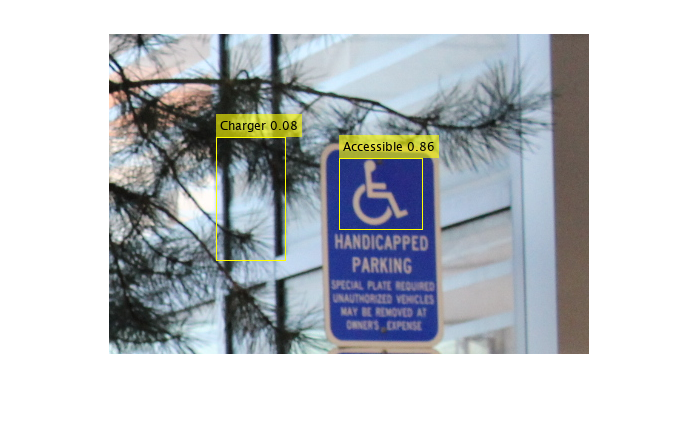

numImages = height(testResults);  % To set a limit on the control
imgIdx = 7;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

## Evaluate detection results

The `evaluateDetectionPrecision` function compares the detection results to the ground truth. The third input argument is the Intersection-over-Union (IoU) threshold used to define a true positive. The default value of 0.5 offers decent location accuracy without being too stringent and causing many false positives. However, change this value based on your application's needs. 

The function returns three outputs. The first is the average precision, AP, for each class, which tells you how well the detector performs for each class. The second and third outputs contain the recall and precision values for each class, sorted by decreasing confidence.

Run the section to evaluate the detector with the specified IoU threshold and look at the output. 

**As a bonus**, save this script with a new name, change the IoU threshold, and compare results.

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.5);
ap

ap =     0.6881
    0.9401
    1.0000


The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP = mean(ap)

mAP = 0.8761

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap2, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.25);
ap2

The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP2 = mean(ap2)

## Visualize precision-recall curves for different classes

Visualizing the precision-recall curves for individual classes gives you more detailed information on your detector. For example, the AP can be low due to low recall, many false positives, or both. 

Use the drop-down menu to select a class and view the precision-recall curves. Compare a few letters, like A, E, C, G, O, and Y. What do the results tell you about the performance of the detector for different classes.

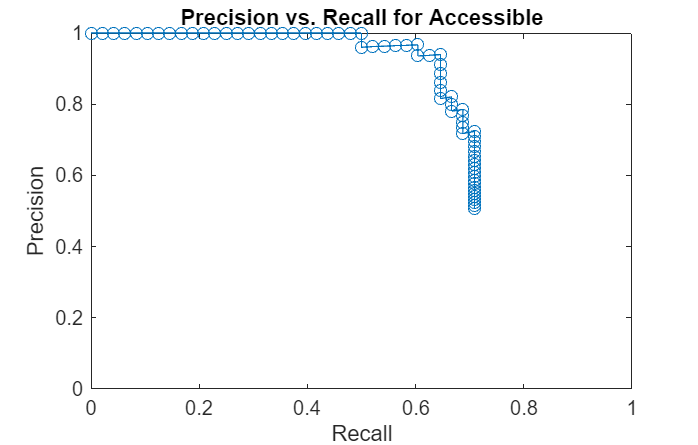

% This drop-down returns the index number for the selected class.
class = 1;
plot(recall{class}, precision{class}, "-o")
title("Precision vs. Recall for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Precision")
xlabel("Recall")

## Choose a detection threshold

An important parameter when detecting objects is the detection threshold value. Only detections with a confidence score greater than or equal to the threshold are returned by the detector. Increasing the threshold helps to limit false positives but can decrease recall as lower-confidence detections are removed. 

To find an appropriate threshold for your detector:

- Create a vector of threshold values to test 

- Run the detector with each threshold value

- Evaluate the detector to determine the AP for each class at each threshold

- Calculate the mAP for each threshold

- Plot the mAP vs. detection threshold

Run the code below to calculate mAP for a series of detection thresholds. 

**Note:** This may take a few minutes because the detector is being applied to every test image at multiple confidence thresholds.

% Vector of detection threshold values to test
thresholds = 0.05:0.05:0.9;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

## Visualize mAP vs detection threshold curve

Ideally, the curve will be relatively flat as you increase the detection threshold. This means that false positives are being suppressed without decreasing recall much. However, increasing the confidence threshold too much will reduce recall, significantly lowering the mAP. In this example, choosing a detection threshold between 0.4 to 0.5 strikes a good balance. 

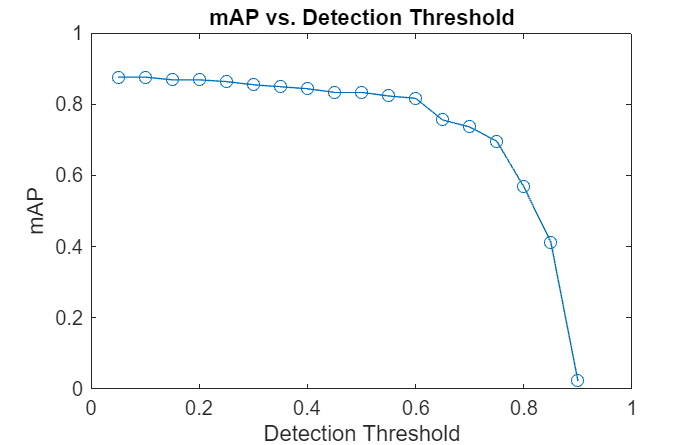

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

## How confident is the detector for each class?

Examine the mAP plot above.

*    A decrease in mAP as detection threshold increases means true positives are lost with the higher threshold.*

But what classes are most affected by the increased detection threshold?

Plotting a row of the `apMatrix` shows how the average precision for an individual class decreases as the detection threshold increases. 

Use the drop-down menu to look at individual classes. An AP that decreases at low detection thresholds means that there are low confidence true postitives. The detector may not be very confident for that class. The letter "E" is an example with this detector.

class = 3;
plot(thresholds, apMatrix(class, :), "-o")
title("AP vs. Detection Threshold for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Average Precision")
xlabel("Detection Threshold")

*Copyright 2024 The MathWorks, Inc.*

## Helper Functions

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end

*Copyright 2024 The MathWorks, Inc.*